## Assignment-1

Find the variation of the Inner wall temperature($T_i$) & Outer wall temperature($T_o$) of the duct with the change of air velocity, if it is known that heat flux provided by the heater is constant $q_o^{\text{''}} =$5000W/m^2. Assume other conditions of the problem are same.

 Also find the Inner and Outer wall temperature at air velocity=15m/s.

Draw a comparative plot of To with velocity in a single graph for

these two situations ( 1. Ti=constant=85 degree centigrade   2. $q_o^{\text{''}}$=constant=5000W/m^2); Use different color of these two plots

## Solution:

## From equivalent thermal circuit: 

## For case-1: Heat flux=constant

 
$$\begin{array}{l}
q_0^{''} =\frac{T_o −T_i }{\frac{t}{k}}=\frac{T_i −T_{\infty } }{\frac{1}{h}}\\
T_i =T_{\infty } +\frac{q_0^{''} }{h}\\
T_o =T_i +q_0^{''} \frac{t}{k}
\end{array}$$


Now convective heat transfer coefficient (h) can be defined using correlation $h=CV^n ,where\text{ }C=10,n=0\ldotp 8$

% Given conditions
T_inf=30; % Temperature of the air in the duct in centigrade
k=20; % Thermal conductivity of duct wall in W/m.K
t=0.01; % Thickness of the duct wall 10mm=0.01m

% h calculation from velocity
v=[1:40]'; % velocity as column vector
C=10;
n=0.8;
h=C*v.^n; % convective heat transfer coefficient

%Case-1: Heat flux q''=5000 SI unit
q_flux=5000; % SI unit

% Inner wall temperature of the duct (Ti) calculation
T_i=T_inf+q_flux./h;
% Outer wall temperature of the duct (To) calculation
T_o=T_i+q_flux*t/k;
%Outer & Inner wall Temperature at velocity 15m/s
v_target=15; % to find out quantities at given v=15m/s
disp(['Outer wall temperature at ',num2str(v_target),' m/s is ',num2str(T_o(v_target)),' degree centigrade']);

Outer wall temperature at 15 m/s is 89.7924 degree centigrade


disp(['Inner wall temperature at ',num2str(v_target),' m/s is ',num2str(T_i(v_target)),' degree centigrade']);

Inner wall temperature at 15 m/s is 87.2924 degree centigrade


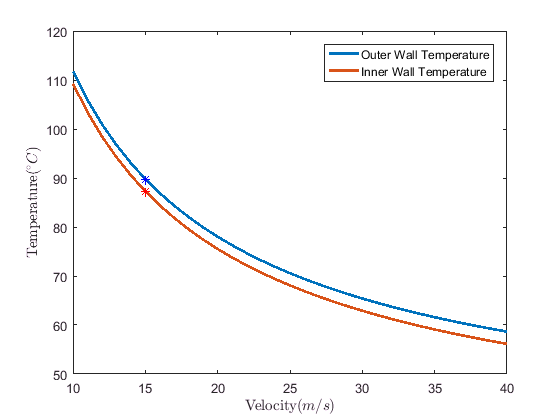

% Variation of To & Ti for case-1 constant heat flux 5000 SI unit
%subplot(2,2,1);
figure(1)
plot(v(10:40),T_o(10:40),v(10:40),T_i(10:40),'LineWidth',2);
xlabel('Velocity($m/s$)','Interpreter','latex');
ylabel('Temperature($^{\circ} C)$','Interpreter','latex');
legend('Outer Wall Temperature','Inner Wall Temperature');
hold on
 plot(v(v_target),T_o(v_target),'b*');plot(v(v_target),T_i(v_target),'r*');
 hold off;

## For Case-2: Inner Wall temperature=constant

Now Heat flux variation can be evaluated by using Newton's law


$$q_o^{\text{''}} =h\left(T_i −T_{\infty } \right)$$
 

Now, Outside wall temperature $T_o$ can be found out by using Fourier's law of heat conduction

 
$$\begin{array}{l}
q_o^{\text{''}} =−k\frac{\left(T_i −T_o \right)}{t}\\
\text{  }{\Rightarrow T}_o =\text{   }\frac{q_o^{\text{''}} t}{k}+T_i 
\end{array}$$


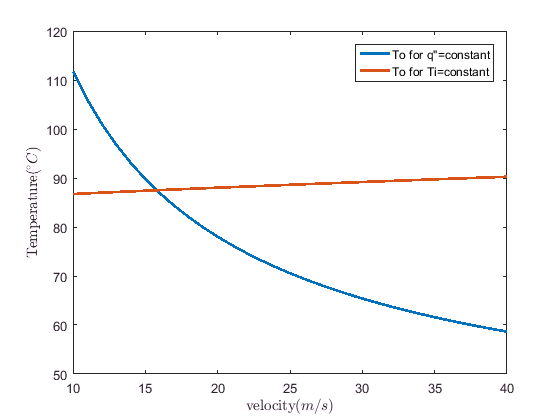

 T_i_2=85; %Constant Inner wall temperature for case-2
 q_flux_2=(T_i_2-T_inf).*h;
 % Outer wall temperature calculation
 T_o_2=T_i_2+(t/k).*q_flux_2;
 
 % Variation of To for case-1 & case-2
 %subplot(2,2,2);
 figure(2)
 plot(v(10:40),T_o(10:40),v(10:40),T_o_2(10:40),'LineWidth',2);
 xlabel('velocity($m/s)$','Interpreter','latex');
 ylabel('Temperature($^{\circ} C)$','Interpreter','latex');
 legend('To for q"=constant','To for Ti=constant');